SOPDT Parameters

K = 3;        
tau1 = 4;     
tau2 = 2;     
theta = 1;    
Ts = 1;       
n = 15;       

Define the transfer function without delay

G_no_delay = tf(K, [tau1*tau2, tau1 + tau2, 1]);

Use a second order Pade approximation to model the time delay.

[N, D] = pade(theta, 2); 
G_delay = tf(N, D);

Combine the system with the delay

G = G_no_delay * G_delay;

Define the time vector for simulation

t = 0:Ts:n*Ts;

Get the step response at discrete intervals

[y, t_out] = step(G, t);

Calculate the step response coefficients (a_i)

a_i = diff([0; y]); 

Display results

delta_u = [1; zeros(n, 1)];
y_i = cumsum(a_i .* delta_u);
i = (0:n)';
step_response_table = table(t_out, i, delta_u, y_i, a_i, ...
    'VariableNames', {'Time (s)', 'i', 'Delta u', 'y_i', 'a_i'});

% Display the table
disp('Step Response Table:');

Step Response Table:


disp(step_response_table);

    Time (s)    i     Delta u    y_i       a_i    
    ________    __    _______    ___    __________

        0        0       1        0              0
        1        1       0        0     -0.0032547
        2        2       0        0        0.15062
        3        3       0        0        0.31705
        4        4       0        0        0.37076
        5        5       0        0        0.36355
        6        6       0        0         0.3285
        7        7       0        0        0.28336
        8        8       0        0        0.23737
        9        9       0        0        0.19499
       10       10       0        0          0.158
       11       11       0        0        0.12677
       12       12       0        0        0.10099
       13       13       0        0       0.080021
       14    

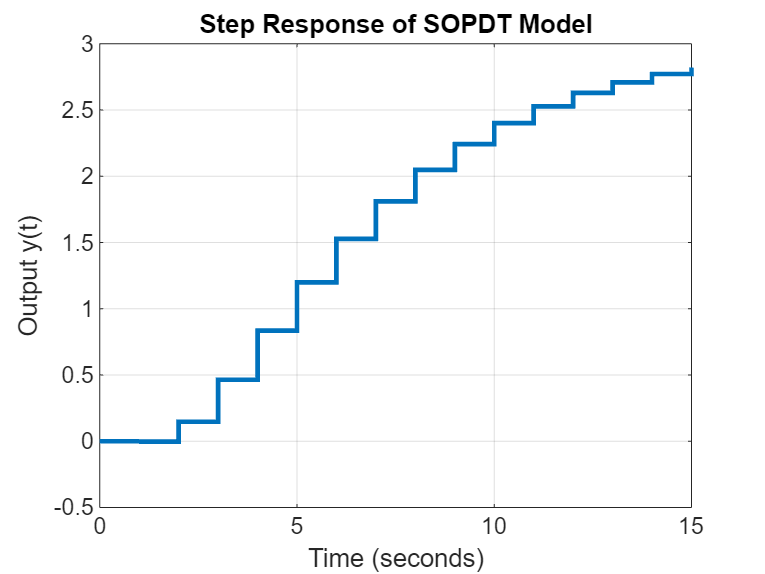



% Plot the step response
figure;
stairs(t_out, y, 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Output y(t)');
title('Step Response of SOPDT Model');
grid on;